# Importing Signals in Subfolders

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code imports the first signal in the data set so that you can see the format of each file. There are three accelerometer signals (x, y, and z).

readmatrix("../data/flooddata/depth_0_0/exp1.csv")

ans =    -0.4660   -1.9130   -1.0220
   -0.9410   -2.2080   -0.3170
    0.6420   -1.1540   -1.0680
    1.5270    1.5750   -1.1850
   -0.1540    4.8160   -0.1980
   -0.4380    0.8440    0.3950
    0.2760   -3.1390    0.7950
   -0.3110   -3.0110   -1.3470
   -0.5390   -0.8970   -1.9500
   -0.4250    3.9840    1.9060


varnames = ["ax" "ay" "az"];

## Tasks 1 & 4-5

Datastores provide a convient way to access data stored in multiple files. For signal data, you can make a signal datastore. By default, `signalDatastore` looks for signal files within the given folder. You can use the `"IncludeSubfolders"` option to look for signals within subfolders of the given folder.

`ds` `=` `signalDatastore``(``"``folder``"``,``...`

`"IncludeSubfolders"``,``true``)`

At the top of the script, you can see that each signal in the first file has three columns, corresponding the acceleration in the x, y, and z directions. But `sigex` only has one column. Where is the rest of the signal?

You can store a variety of information about a signal in a .csv file, like labels, time values, or other channels. So by default, `signalDatastore` only imports the first variable in your files. You can customize this with the `"SignalVariableNames"` option.

`ds` `=` `signalDatastore``(``"``folder``"``,``...`

`"SignalVariableNames"``,``[``"Var1"` `"Var2"``])`

By default, `signalDatastore` assumes that each variable in your file is a separate signal, so the output is a column of signal vectors. But for this data set, each time step of the signal has three values, or the signal has three *channels*.

To visualize the signal in the next task, you'll turn convert this variable to matrix. Right now, the columns will concatenate into one long matrix. To visualize each channel, you can change the variable output orientation from column to row.

`ds` `=` `signalDatastore``(``"``folder``"``,``...`

`"ReadOutputOrientation"``,``"row"``)`

sigds = signalDatastore("../data/flooddata", "IncludeSubfolders", true);
sigds = signalDatastore("../data/flooddata", "IncludeSubfolders", true, "SignalVariableNames", varnames);
sigds = signalDatastore("../data/flooddata", "IncludeSubfolders", true, "SignalVariableNames", varnames, "ReadOutputOrientation", "row");

## Task 2

The properties of the datastore contain the meta information about the data files.

fname = sigds.Files

fname = 222×1 cell array
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp1.csv' }
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp10.csv'}
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp11.csv'}
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp12.csv'}
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp13.csv'}
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp14.csv'}
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp15.csv'}
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp16.csv'}
    {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\flooddata\depth_0_0\exp17.csv'}
    {'C:\Users\luisa\

## Task 3

You can use the `read` function to import the data from a file in the datastore.

`data` `=` `read``(``ds``)`

Using the `read` function the first time will import the data from the first file. Using it a second time will import the data from the second file, and so on.

sigex = read(sigds)

sigex = 1×3 cell array
    {106×1 double}    {106×1 double}    {106×1 double}


## Task 6

The signal `sigex` is in a cell array. To visualize the signal, you can convert it to a matrix with `cell2mat`.

`datamatrix` `=` `cell2mat``(``datacell``)`

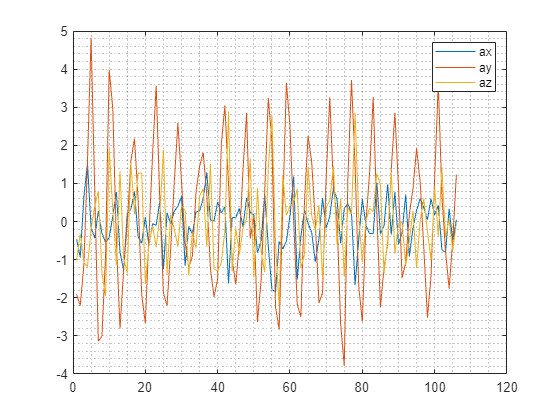

sig = cell2mat(sigex);
plot(sig)
grid minor;
legend(varnames)